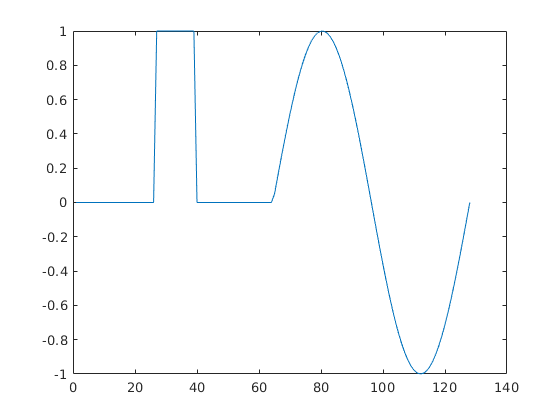

clc;
clear;
close all;

rng('default');

% Number of discretization points
N = 128;
gamma = 0.03;
C = 1 / (sqrt(2*pi)*gamma);

K = zeros(N,N);
h = 1/N;
x = linspace(0,1,N)';

% discrete convolution matrix
for l = 1:N
    for k = 1:N
    	K(l,k) = h * C * exp(-(l-k)^2 * h^2 / (2 * gamma^2));
    end
end

% true image
m_true = (x > .2).*(x < .3) + sin(4*pi*x).*(x > 0.5);
figure; plot(m_true);

% convolved image
d = K * m_true;

% C) Reconstruct m using the Landweber method. Report convergence history
% (i.e. residual and error norms at each iteration)


% D) Add normally distributed noise, and reconstruct m using the Landweber
% method. Report convergence history
dn = d + 0.01 * randn(N,1);

% E) Use L-curve to find out when to stop.